**LAB WEEK 12**

**Muhammad Asad Imran Rafique**

**48065145**

**a)**

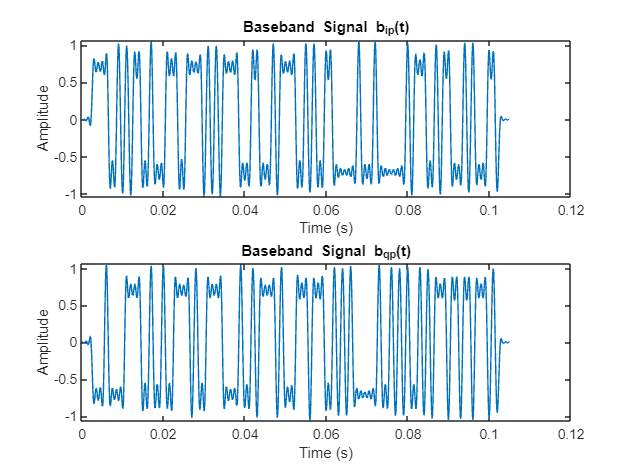

Nbit = 200;
fs = 10000;
Rsym = 1000;
Tsym = 1/Rsym;
Nsps = Tsym*fs;
Es = 1;
Eb = Es/2;
M = 4;
k = log2(M);

m = randi([0 1], 1, Nbit);

I_bits = m(1:k:end);
Q_bits = m(2:k:end);

I = sqrt(Eb)*(2*I_bits - 1);
Q = sqrt(Eb)*(2*Q_bits - 1);

beta = 1;
span = 6;
sps = fs/Rsym;

h = rcosdesign(beta, span, sps, 'sqrt');
h = h/norm(h) * sqrt(Nsps);


bip = upfirdn(I, h, Nsps);
bqp = upfirdn(Q, h, Nsps);

t = (0:length(bip)-1) / fs;

figure;
subplot(2,1,1);
plot(t, bip);
title('Baseband Signal b_{ip}(t)');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2,1,2);
plot(t, bqp);
title('Baseband Signal b_{qp}(t)');
xlabel('Time (s)');
ylabel('Amplitude');

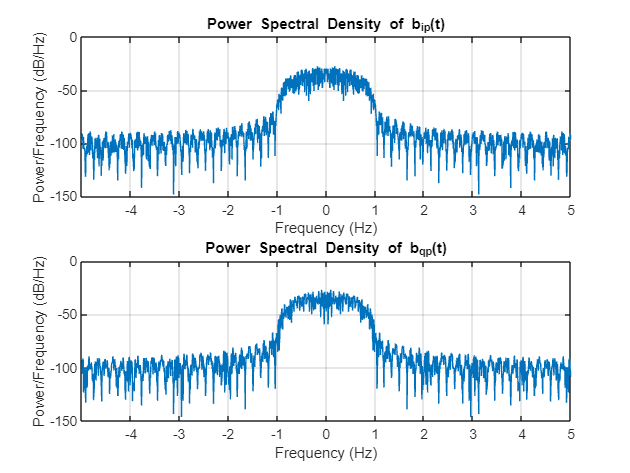


figure;
subplot(2,1,1);
periodogram(bip, [], [], fs, 'centered');
title('Power Spectral Density of b_{ip}(t)');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');

subplot(2,1,2);
periodogram(bqp, [], [], fs, 'centered');
title('Power Spectral Density of b_{qp}(t)');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');

**b)**

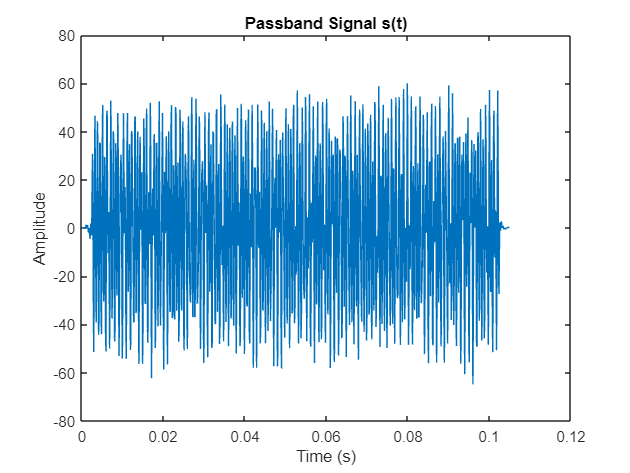

fc = 1600;
phi = sqrt(2*Rsym);
s_t = phi * (bip .* cos(2 * pi * fc * t) - bqp .* sin(2 * pi * fc * t));

figure;
plot(t, s_t);
title('Passband Signal s(t)');
xlabel('Time (s)');
ylabel('Amplitude');

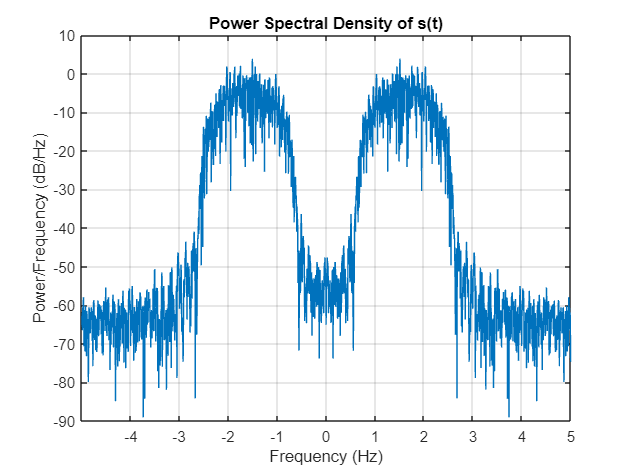

figure;
periodogram(s_t, [], [], fs, 'centered');
title('Power Spectral Density of s(t)');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');

energy_per_symbol = sum(abs(s_t).^2)/(fs*Nbit/2);
energy_per_symbol

energy_per_symbol = 1.0000

**c)**

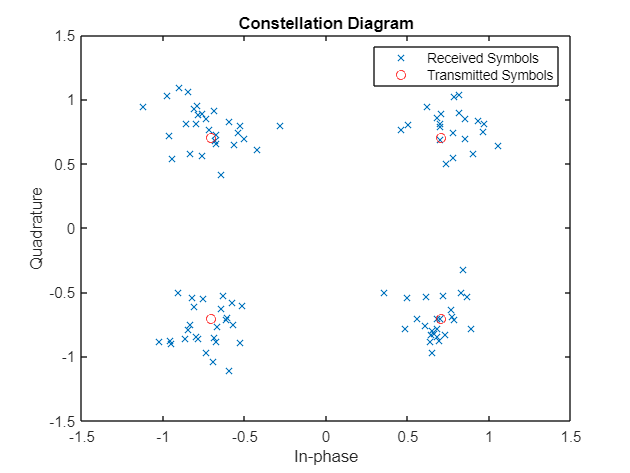

SNR_dB = 10;
SNR_linear = 10^(SNR_dB/10);
N0 = energy_per_symbol / (2 * SNR_linear);
noise_std = sqrt(N0 * fs / 2);
w_t = noise_std * randn(size(s_t));

r_t = s_t+w_t;

r_bip = r_t .* cos(2 * pi * fc * t) * sqrt(2*Rsym);
r_bqp = -r_t .* sin(2 * pi * fc * t) * sqrt(2*Rsym);

r_bip_filt = filter(h,1,r_bip)/fs;
r_bqp_filt = filter(h,1,r_bqp)/fs;

r_bip_samp = r_bip_filt(length(h):sps:end);
r_bqp_samp = r_bqp_filt(length(h):sps:end);


figure;
plot(r_bip_samp, r_bqp_samp, 'x');
hold on;
plot(I, Q, 'ro');
legend('Received Symbols', 'Transmitted Symbols');
title('Constellation Diagram');
xlabel('In-phase');
ylabel('Quadrature');

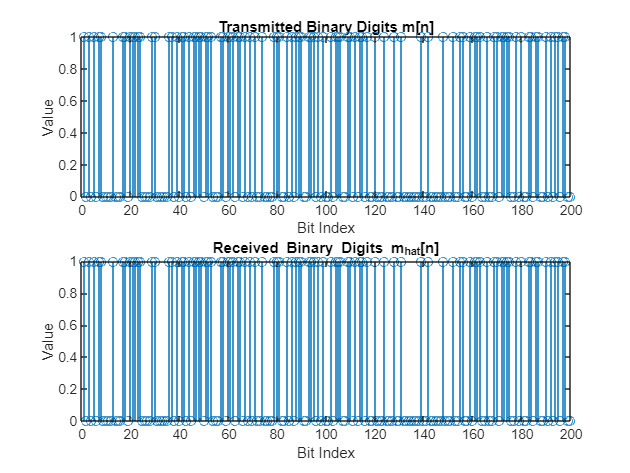


dec_I = r_bip_samp > 0;
dec_Q = r_bqp_samp > 0;

m_hat = zeros(1, 2*length(dec_I));
m_hat(1:2:end) = dec_I;
m_hat(2:2:end) = dec_Q;

figure;
subplot(2,1,1);
stem(m);
title('Transmitted Binary Digits m[n]');
xlabel('Bit Index');
ylabel('Value');

subplot(2,1,2);
stem(m_hat);
title('Received Binary Digits m_{hat}[n]');
xlabel('Bit Index');
ylabel('Value');

Nerr = sum(m~=m_hat);
Nerr

Nerr = 0

**d)**

Nbit_large = 1e5;

m_large = randi([0, 1], 1, Nbit_large);
symbols_large = 2*m_large(1:2:end) + m_large(2:2:end);
symbols_large = 2*symbols_large - 3; % Map [0,1,2,3] to [-3,-1,1,3]

I_large = sqrt(Eb)*symbols_large(1:2:end);
Q_large = sqrt(Eb)*symbols_large(2:2:end);

bip_large = upfirdn(I_large, h, Nsps);
bqp_large = upfirdn(Q_large, h, Nsps);
t_large = (0:length(bip_large)-1) / fs;
s_large = phi * (bip_large .* cos(2*pi*fc*t_large) - bqp_large .* sin(2*pi*fc*t_large));

BER = zeros(1, 101);
Eb_N0_dB = 0:0.1:10;

for k = 1:length(Eb_N0_dB)
    snr_linear_large = 10^(Eb_N0_dB(k)/10);
    N0_large = Es / (2*snr_linear_large);
    w_large = sqrt(N0_large/2) * randn(size(s_large));
    r_large = s_large + w_large;
    r_i_large = 2 * r_large .* cos(2*pi*fc*t_large(1:length(r_large)));
    r_q_large = -2 * r_large .* sin(2*pi*fc*t_large(1:length(r_large)));
    r_i_filt_large = filter(h, 1, r_i_large);
    r_q_filt_large = filter(h, 1, r_q_large);
    r_i_down_large = r_i_filt_large(span*sps+1:end-span*sps);
    r_q_down_large = r_q_filt_large(span*sps+1:end-span*sps);
    r_i_sym_large = r_i_down_large(1:sps:end);
    r_q_sym_large = r_q_down_large(1:sps:end);
    m_est_i_large = r_i_sym_large > 0;
    m_est_q_large = r_q_sym_large > 0;
    m_est_large = zeros(1, Nbit_large);
    m_est_large(1:2:end) = m_est_i_large;
    m_est_large(2:2:end) = m_est_q_large;
    Nerr_large = sum(m_large ~= m_est_large);
    BER(k) = Nerr_large / Nbit_large;
end

Unable to perform assignment because the left and right sides have a different number of elements.


% Plot BER vs Eb/N0
figure;
semilogy(Eb_N0_dB, BER, 'b-o');
hold on;
theory_BER = qfunc(sqrt(2 * 10.^(Eb_N0_dB/10)));
semilogy(Eb_N0_dB, theory_BER, 'r--');
title('BER vs. Eb/N0 for QPSK');
xlabel('Eb/N0 (dB)');
ylabel('Bit Error Rate');
legend('Simulation', 'Theory');
grid on;